# 根据经纬度，绘制地理图连线

关注**微信公众号：数学建模BOOM**，回复“**群**”，本文件geoline.mlx，和更多数模学习资料在群文件；在b站同名的up主有视频讲解（主讲人：北海）

基本形式：geoplot(lat,lon)，lat即latitude，纬度；lon即longitude，经度；

使用函数 geoplot需要联网，其中输入的第一个变量是纬度，第二个是经度，注意不要搞反了。正数代表东经和北纬，负数代表西经和南纬

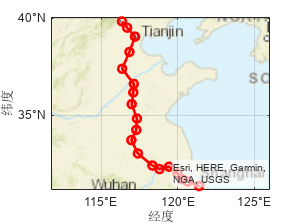

clear,clc
citys = [116.350009,39.853928; 116.683546,39.538304; 117.201509,39.085318; 116.838715,38.304676;...
        116.359244,37.436492;  117.120128,36.652069; 117.086963,36.201784; 116.986212,35.581933;...
        117.323759,34.810858;  117.283752,34.204224; 116.96419,33.647726;  117.388566,32.91682;...
        118.333439,32.255904;  118.796624,32.059344; 119.424441,32.188141; 119.974092,31.811313;...
        120.311889,31.491064;  120.642391,31.369189; 121.380857,31.112834];

lat = citys(:,2);
lon = citys(:,1);

geoplot(lat,lon,"r-o","LineWidth",2)
geobasemap streets

`geobasemap设置地图类型，默认为streets-light，还可设为公路图streets，卫星图satellite，地质图topographic，地表湿度colorterrain，浅绿bluegreen等`

# 如何获取地图上某点的经纬度数据

高德坐标拾取器：https://lbs.amap.com/tools/picker/

需要登录注册为个人开发者，可免费使用获取经纬度